# staticな学習データをGPR

テストデータとも比較して，精度も確認する．

シンプルに解いて，オイラーの回転運動方程式を解いてlight curveを計算して，比較する．

csvの中身：

- xTrain: [q, satPos, obsPos, sunPos]

- yTrain: [mApp]

clc
clear

### add path for functions

curdir = pwd;
addpath(genpath(strcat(curdir, '/../../yoshimuLibrary/')));
addpath(genpath(strcat(curdir, '/../../hara_functions/')));
addpath(strcat(curdir, '/../../gpryui/'));

tStart = tic;

### input values directly

% inputGP = "attitude"
% inputGP = "attitude, mApp_pastMean" % "attitude, mApp_pastMean" or "attitude, position, mApp_pastMean" or "attitude, relativePosition, mApp_pastMean"
% inputGP = "attitude, position, mApp_pastMean" % [q, r, obsECI, mApp_past]
inputGP = "attitude, relativePosition, mApp_pastMean"

inputGP = "attitude, relativePosition, mApp_pastMean"


predictionStep = 1; % 1:ode, 2: simpleGP as a prediction model
validData = "boxWing_lcAtti_onOrbit.mat"

validData = "boxWing_lcAtti_onOrbit.mat"


tau = log(1);
sigma = log(0.25);
eta = log(0.1);
params = [tau, sigma, eta]; % hyper parameters

tstep = 1;
% tspan = 0:tstep:60*3;
tstep_span = [0, tstep];

tSpanPast = 20;

### read data

% read train data ------
datadir = strcat(curdir, '/../../data/static/');
cddir = datadir;
cd(cddir)
trainStruct = dir('*.csv');
trainDF = [];
for i = 1:1:size(trainStruct, 1)
    fName = trainStruct(i).name;
    df = readmatrix(fName); % [t_jd, mApp, q, r, obsECI, sunPosI, mApp_pastMean], nIniCon x 16
    trainDF = [trainDF; df];
end
cd(curdir)

% read valid data -----
valid = load(validData); % [t_, mApp, q, phi, theta, psi, w, sat, r, v, obsECI, sunPosI, jdHistory]

### data handling

% train data ------

outputDim = 1; % [mApp]
if strcmp(inputGP, "attitude, position, mApp_pastMean")
    % inputDim = 11; % [q, r, obsECI, mApp_pastMean], nx11, sunPosI はほぼ動いてないとして入力に入れない
    x_train = trainDF(:,3:end);

    % 入力のorderを揃えたい
    x_train_q = x_train(:,1:4);
    x_train_r = x_train(:,5:7);
    x_train_obsECI = x_train(:,8:10);
    x_train_sunPosI = x_train(:,11:13);
    x_train_mApp_pastMean = x_train(:,14);

    % x_train_r = x_train_r ./ max(x_train_r, [], "all");
    % x_train_obsECI = x_train_obsECI ./ max(x_train_obsECI, [], "all");
    r_valid_max = max(valid.r, [], "all");
    obsECI_valid_max = max(valid.obsECI, [], "all");
    x_train_r = x_train_r ./ r_valid_max;
    x_train_obsECI = x_train_obsECI ./ obsECI_valid_max;

    % x_trainを決定k
    x_train = [x_train_q, x_train_r, x_train_obsECI, x_train_mApp_pastMean];
    inputDim = size(x_train, 2);

elseif strcmp(inputGP, "attitude, relativePosition, mApp_pastMean")
    x_train = trainDF(:,3:end);

    x_train_q = x_train(:,1:4);
    x_train_r = x_train(:,5:7);
    x_train_obsECI = x_train(:,8:10);
    x_train_obsToTarget = x_train_r - x_train_obsECI;
    x_train_sunPosI = x_train(:,11:13);
    x_train_mApp_pastMean = x_train(:,14);

    obsToTarget_valid_max = max(valid.r - valid.obsECI, [], "all"); % 相対位置の最大値を取得 for order調整
    x_train_obsToTarget = x_train_obsToTarget ./ obsToTarget_valid_max;

    % x_trainを決定k
    x_train = [x_train_q, x_train_obsToTarget, x_train_mApp_pastMean];
    inputDim = size(x_train, 2);

elseif strcmp(inputGP, "attitude, mApp_pastMean")
    % inputDim = 5; % [q, mApp_pastMean]
    x_train = [trainDF(:,3:6), trainDF(:,end)]; % [q, mApp_pastMean]
    inputDim = size(x_train, 2);
elseif strcmp(inputGP, "attitude")
    x_train = trainDF(:,3:6); % [q]
    inputDim = size(x_train, 2);
end
y_train = trainDF(:, 2); % [mApp]

size(x_train)

ans =        46224           8


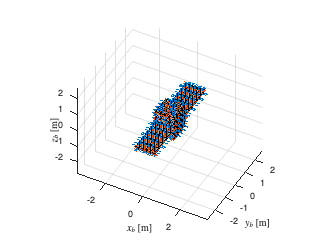


% light curve の inf を処理
y_train(isinf(y_train)) = NaN;
y_train = fillmissing(y_train, 'previous'); % mAppのinfを直前の値に置換
x_train(isinf(x_train)) = NaN;
x_train = fillmissing(x_train, 'previous'); % mApp_pastMeanの inf 処理
valid.mApp(isinf(valid.mApp)) = NaN;
valid.mApp = fillmissing(valid.mApp, 'previous'); % 真値のmAppも処理

% train data の各スカラー出力の平均を0にする for GPR
y_train_mean = mean(y_train); % [1, 1]
y_train = y_train - y_train_mean; % [:, 1], broadcasting


% valid data
t_ = valid.t_;
sat = valid.sat;
showSC(sat, "Normal", "on") % visualize satellite

### create a GP model (x_train, y_train, y_train_mean, K_Dp, Kinv_Dp, K_Do, Kinv_Do) as a .mat file

tStartLearning = tic;
% [K_Dp, Kinv_Dp] = kernelMatrix(x_train, params); % x_train = [mApp, q, w]
K_Dp = 0; Kinv_Dp = 0; % 時間短縮のために一旦0で．．

[K_Do, Kinv_Do] = kernelMatrix(x_train(:,1:inputDim), params); % 
tEndLearning = toc(tStartLearning) / 60;
strcat("calculation time for learning [min] : ", num2str(tEndLearning))

ans = "calculation time for learning [min] : 171.5338"

fName = 'constGP';
save(strcat(fName, '.mat'), 'x_train', 'y_train', 'y_train_mean', 'K_Dp', 'Kinv_Dp', 'K_Do', 'Kinv_Do', 'params', '-v7.3');

## 逐次的に回帰を行い，回帰モデルの精度を確認

### conditions for ode

const = orbitConst; % for orbital motion
earthVSOP = vsopConst; % for earth orientation

% for time calculation
iau06 = readIAU06;
leapJD = leapS; % load database
fname = "EOP_20_C04_one_file_1962-now.txt";
eopDataAll = readEOP(fname);

tle = readTLE('JCSAT2_edited.txt', const);
jd = tle.jd;

obsLon = deg2rad(130.216544); % [rad], longitude
obsLat = deg2rad(33.3594649); % [rad], latitude
[obsPosECEF(1), obsPosECEF(2), obsPosECEF(3)] = sph2cart(obsLon, obsLat, const.RE); % [km], observer position @ECEF(Earth Centered Earth Fixed)
obsPosECEF = obsPosECEF .* 10^3; % [m], 1x3 vec

rIni = valid.r(1,:);
vIni = valid.v(1,:);
qIni = valid.q(1,:);
wIni = valid.w(1,:);

xIni = [rIni, vIni, qIni, wIni];

obsECIIni = valid.obsECI(1,:);
sunPosIIni = valid.sunPosI(1,:);
mApp_pastMeanIni = valid.mApp(1,1);

obsToTargetIni = rIni - obsECIIni;

% 相対的な精度誤差（計算解の正しい桁数を制御），絶対許容誤差（計算解と真の解との差を制御）
options = odeset('RelTol', 1e-10, 'AbsTol', 1e-10); 

### ode と gpr を回して逐次的に回帰

% preallocation
x_reg = zeros(size(t_, 1), inputDim); % preallocation [q, satPos, obsPos, sunPos]. inputs for regression
if strcmp(inputGP, "attitude, position, mApp_pastMean")
    x_reg(1,:) = [qIni, rIni./r_valid_max, obsECIIni./obsECI_valid_max, mApp_pastMeanIni]; % 初期値は真値
elseif strcmp(inputGP, "attitude, relativePosition, mApp_pastMean")
    x_reg(1,:) = [qIni, obsToTargetIni./obsToTarget_valid_max, mApp_pastMeanIni]; % 初期値は真値
elseif strcmp(inputGP, "attitude, mApp_pastMean")
    x_reg = [qIni, mApp_pastMeanIni];
elseif strcmp(inputGP, "attitude")
    x_reg = [qIni];
end

x_ode = zeros(size(t_, 1), size(xIni, 2));
x_ode(1,:) = xIni;

y_reg_mu = zeros(size(t_,1), outputDim); % [mApp]
y_reg_var = zeros(size(y_reg_mu));
y_reg = zeros(size(y_reg_mu));

for i = 1:1:size(t_, 1)-1

the number of the time step i: 1 


the calculation time to go forward to the next step: 0.315441 [min]


the number of the time step i: 2 


the calculation time to go forward to the next step: 0.010690 [min]


the number of the time step i: 3 


the calculation time to go forward to the next step: 0.013573 [min]


the number of the time step i: 4 


the calculation time to go forward to the next step: 0.010172 [min]


the number of the time step i: 5 


the calculation time to go forward to the next step: 0.010654 [min]


the number of the time step i: 6 


the calculation time to go forward to the next step: 0.013612 [min]


the number of the time step i: 7 


the calculation time to go forward to the next step: 0.066440 [min]


the number of the time step i: 8 


the calculation time to go forward to the next step: 0.034292 [min]


the number of the time step i: 9 


the calculation time to go forward to the next step: 0.010038 [min]


the number of the time step i: 10 


the calculation time to go forward to the next step: 0.009971 [min]


the number of the time step i: 11 


the calculation time to go forward to the next step: 0.010048 [min]


the number of the time step i: 12 


the calculation time to go forward to the next step: 0.009942 [min]


the number of the time step i: 13 


the calculation time to go forward to the next step: 0.010184 [min]


the number of the time step i: 14 


the calculation time to go forward to the next step: 0.010005 [min]


the number of the time step i: 15 


the calculation time to go forward to the next step: 0.010208 [min]


the number of the time step i: 16 


the calculation time to go forward to the next step: 0.010127 [min]


the number of the time step i: 17 


the calculation time to go forward to the next step: 0.055031 [min]


the number of the time step i: 18 


the calculation time to go forward to the next step: 0.040747 [min]


the number of the time step i: 19 


the calculation time to go forward to the next step: 0.009986 [min]


the number of the time step i: 20 


the calculation time to go forward to the next step: 0.009971 [min]


the number of the time step i: 21 


the calculation time to go forward to the next step: 0.009918 [min]


the number of the time step i: 22 


the calculation time to go forward to the next step: 0.009934 [min]


the number of the time step i: 23 


the calculation time to go forward to the next step: 0.009955 [min]


the number of the time step i: 24 


the calculation time to go forward to the next step: 0.010184 [min]


the number of the time step i: 25 


the calculation time to go forward to the next step: 0.009996 [min]


the number of the time step i: 26 


the calculation time to go forward to the next step: 0.063666 [min]


the number of the time step i: 27 


the calculation time to go forward to the next step: 0.010380 [min]


the number of the time step i: 28 


the calculation time to go forward to the next step: 0.010791 [min]


the number of the time step i: 29 


the calculation time to go forward to the next step: 0.010675 [min]


the number of the time step i: 30 


the calculation time to go forward to the next step: 0.009928 [min]


the number of the time step i: 31 


the calculation time to go forward to the next step: 0.009943 [min]


the number of the time step i: 32 


the calculation time to go forward to the next step: 0.070782 [min]


the number of the time step i: 33 


the calculation time to go forward to the next step: 0.016692 [min]


the number of the time step i: 34 


the calculation time to go forward to the next step: 0.010088 [min]


the number of the time step i: 35 


the calculation time to go forward to the next step: 0.009967 [min]


the number of the time step i: 36 


the calculation time to go forward to the next step: 0.009939 [min]


the number of the time step i: 37 


the calculation time to go forward to the next step: 0.010003 [min]


the number of the time step i: 401 


the calculation time to go forward to the next step: 0.010117 [min]


the number of the time step i: 402 


the calculation time to go forward to the next step: 0.012375 [min]


the number of the time step i: 403 


the calculation time to go forward to the next step: 0.011223 [min]


the number of the time step i: 404 


the calculation time to go forward to the next step: 0.009910 [min]


the number of the time step i: 405 


the calculation time to go forward to the next step: 0.010824 [min]


the number of the time step i: 406 


the calculation time to go forward to the next step: 0.103609 [min]


the number of the time step i: 407 


the calculation time to go forward to the next step: 0.009904 [min]


the number of the time step i: 408 


the calculation time to go forward to the next step: 0.009948 [min]


the number of the time step i: 409 


the calculation time to go forward to the next step: 0.010630 [min]


the number of the time step i: 410 


the calculation time to go forward to the next step: 0.009956 [min]


the number of the time step i: 411 


the calculation time to go forward to the next step: 0.009896 [min]


the number of the time step i: 412 


the calculation time to go forward to the next step: 0.009862 [min]


the number of the time step i: 413 


the calculation time to go forward to the next step: 0.014858 [min]


the number of the time step i: 414 


the calculation time to go forward to the next step: 0.023179 [min]


the number of the time step i: 415 


the calculation time to go forward to the next step: 0.012490 [min]


the number of the time step i: 416 


the calculation time to go forward to the next step: 0.009966 [min]


the number of the time step i: 417 


the calculation time to go forward to the next step: 0.009905 [min]


the number of the time step i: 418 


the calculation time to go forward to the next step: 0.010781 [min]


the number of the time step i: 419 


the calculation time to go forward to the next step: 0.010873 [min]


the number of the time step i: 420 


the calculation time to go forward to the next step: 0.009870 [min]


the number of the time step i: 421 


the calculation time to go forward to the next step: 0.009934 [min]


the number of the time step i: 422 


the calculation time to go forward to the next step: 0.085581 [min]


the number of the time step i: 423 


the calculation time to go forward to the next step: 0.009964 [min]


the number of the time step i: 424 


the calculation time to go forward to the next step: 0.009857 [min]


the number of the time step i: 425 


the calculation time to go forward to the next step: 0.009883 [min]


the number of the time step i: 426 


the calculation time to go forward to the next step: 0.009950 [min]


the number of the time step i: 427 


the calculation time to go forward to the next step: 0.009862 [min]


the number of the time step i: 428 


the calculation time to go forward to the next step: 0.009913 [min]


the number of the time step i: 429 


the calculation time to go forward to the next step: 0.009885 [min]


the number of the time step i: 430 


the calculation time to go forward to the next step: 0.009988 [min]


the number of the time step i: 431 


the calculation time to go forward to the next step: 0.010058 [min]


the number of the time step i: 432 


the calculation time to go forward to the next step: 0.009915 [min]


the number of the time step i: 433 


the calculation time to go forward to the next step: 0.009974 [min]


the number of the time step i: 434 


the calculation time to go forward to the next step: 0.009886 [min]


the number of the time step i: 435 


the calculation time to go forward to the next step: 0.009894 [min]


the number of the time step i: 436 


the calculation time to go forward to the next step: 0.010003 [min]


the number of the time step i: 437 


the calculation time to go forward to the next step: 0.010035 [min]


the number of the time step i: 438 


the calculation time to go forward to the next step: 0.009897 [min]


the number of the time step i: 439 


the calculation time to go forward to the next step: 0.053623 [min]


the number of the time step i: 440 


the calculation time to go forward to the next step: 0.010748 [min]


the number of the time step i: 441 


the calculation time to go forward to the next step: 0.009980 [min]


the number of the time step i: 442 


the calculation time to go forward to the next step: 0.009908 [min]


the number of the time step i: 443 


the calculation time to go forward to the next step: 0.010066 [min]


the number of the time step i: 444 


the calculation time to go forward to the next step: 0.009930 [min]


the number of the time step i: 445 


the calculation time to go forward to the next step: 0.010002 [min]


the number of the time step i: 446 


the calculation time to go forward to the next step: 0.009916 [min]


the number of the time step i: 447 


the calculation time to go forward to the next step: 0.009894 [min]


the number of the time step i: 448 


the calculation time to go forward to the next step: 0.023590 [min]


the number of the time step i: 449 


the calculation time to go forward to the next step: 0.009920 [min]


the number of the time step i: 450 


the calculation time to go forward to the next step: 0.009947 [min]


the number of the time step i: 451 


the calculation time to go forward to the next step: 0.009945 [min]


the number of the time step i: 452 


the calculation time to go forward to the next step: 0.010005 [min]


the number of the time step i: 453 


the calculation time to go forward to the next step: 0.011327 [min]


the number of the time step i: 454 


the calculation time to go forward to the next step: 0.010021 [min]


the number of the time step i: 455 


the calculation time to go forward to the next step: 0.009958 [min]


the number of the time step i: 456 


the calculation time to go forward to the next step: 0.010813 [min]


the number of the time step i: 457 


the calculation time to go forward to the next step: 0.079838 [min]


the number of the time step i: 458 


the calculation time to go forward to the next step: 0.010007 [min]


the number of the time step i: 459 


the calculation time to go forward to the next step: 0.009951 [min]


the number of the time step i: 460 


the calculation time to go forward to the next step: 0.009928 [min]


the number of the time step i: 461 


the calculation time to go forward to the next step: 0.009960 [min]


the number of the time step i: 462 


the calculation time to go forward to the next step: 0.009952 [min]


the number of the time step i: 463 


the calculation time to go forward to the next step: 0.009913 [min]


the number of the time step i: 464 


the calculation time to go forward to the next step: 0.009934 [min]


the number of the time step i: 465 


the calculation time to go forward to the next step: 0.009915 [min]


the number of the time step i: 466 


the calculation time to go forward to the next step: 0.009939 [min]


the number of the time step i: 467 


the calculation time to go forward to the next step: 0.010086 [min]


the number of the time step i: 468 


the calculation time to go forward to the next step: 0.009940 [min]


the number of the time step i: 469 


the calculation time to go forward to the next step: 0.009937 [min]


the number of the time step i: 470 


the calculation time to go forward to the next step: 0.010276 [min]


the number of the time step i: 471 


the calculation time to go forward to the next step: 0.009964 [min]


the number of the time step i: 472 


the calculation time to go forward to the next step: 0.010158 [min]


the number of the time step i: 473 


the calculation time to go forward to the next step: 0.009940 [min]


the number of the time step i: 474 


the calculation time to go forward to the next step: 0.009981 [min]


the number of the time step i: 475 


the calculation time to go forward to the next step: 0.009958 [min]


the number of the time step i: 476 


the calculation time to go forward to the next step: 0.009906 [min]


the number of the time step i: 477 


the calculation time to go forward to the next step: 0.009918 [min]


the number of the time step i: 478 


the calculation time to go forward to the next step: 0.009961 [min]


the number of the time step i: 479 


the calculation time to go forward to the next step: 0.009989 [min]


the number of the time step i: 480 


the calculation time to go forward to the next step: 0.009965 [min]


the number of the time step i: 481 


the calculation time to go forward to the next step: 0.009964 [min]


the number of the time step i: 482 


the calculation time to go forward to the next step: 0.009991 [min]


the number of the time step i: 483 


the calculation time to go forward to the next step: 0.010196 [min]


the number of the time step i: 484 


the calculation time to go forward to the next step: 0.009994 [min]


the number of the time step i: 485 


the calculation time to go forward to the next step: 0.009953 [min]


the number of the time step i: 486 


the calculation time to go forward to the next step: 0.009967 [min]


the number of the time step i: 487 


the calculation time to go forward to the next step: 0.009978 [min]


the number of the time step i: 488 


the calculation time to go forward to the next step: 0.009990 [min]


the number of the time step i: 489 


the calculation time to go forward to the next step: 0.009939 [min]


the number of the time step i: 490 


the calculation time to go forward to the next step: 0.009960 [min]


the number of the time step i: 491 


the calculation time to go forward to the next step: 0.009918 [min]


the number of the time step i: 492 


the calculation time to go forward to the next step: 0.009965 [min]


the number of the time step i: 493 


the calculation time to go forward to the next step: 0.010163 [min]


the number of the time step i: 494 


the calculation time to go forward to the next step: 0.010178 [min]


the number of the time step i: 495 


the calculation time to go forward to the next step: 0.010067 [min]


the number of the time step i: 496 


the calculation time to go forward to the next step: 0.009986 [min]


the number of the time step i: 497 


the calculation time to go forward to the next step: 0.010094 [min]


the number of the time step i: 498 


the calculation time to go forward to the next step: 0.010081 [min]


the number of the time step i: 499 


the calculation time to go forward to the next step: 0.010114 [min]


the number of the time step i: 500 


the calculation time to go forward to the next step: 0.010022 [min]


the number of the time step i: 501 


the calculation time to go forward to the next step: 0.010064 [min]


the number of the time step i: 502 


the calculation time to go forward to the next step: 0.016975 [min]


the number of the time step i: 503 


the calculation time to go forward to the next step: 0.019915 [min]


the number of the time step i: 504 


the calculation time to go forward to the next step: 0.010058 [min]


the number of the time step i: 505 


the calculation time to go forward to the next step: 0.010008 [min]


the number of the time step i: 506 


the calculation time to go forward to the next step: 0.015773 [min]


the number of the time step i: 507 


the calculation time to go forward to the next step: 0.012129 [min]


the number of the time step i: 508 


the calculation time to go forward to the next step: 0.010325 [min]


the number of the time step i: 509 


the calculation time to go forward to the next step: 0.010007 [min]


the number of the time step i: 510 


the calculation time to go forward to the next step: 0.009985 [min]


the number of the time step i: 511 


the calculation time to go forward to the next step: 0.009970 [min]


the number of the time step i: 512 


the calculation time to go forward to the next step: 0.023910 [min]


the number of the time step i: 513 


the calculation time to go forward to the next step: 0.011922 [min]


the number of the time step i: 514 


the calculation time to go forward to the next step: 0.009956 [min]


the number of the time step i: 515 


the calculation time to go forward to the next step: 0.010116 [min]


the number of the time step i: 516 


the calculation time to go forward to the next step: 0.009934 [min]


the number of the time step i: 517 


the calculation time to go forward to the next step: 0.009970 [min]


the number of the time step i: 518 


the calculation time to go forward to the next step: 0.040676 [min]


the number of the time step i: 519 


the calculation time to go forward to the next step: 0.010422 [min]


the number of the time step i: 520 


the calculation time to go forward to the next step: 0.009926 [min]


the number of the time step i: 521 


the calculation time to go forward to the next step: 0.009948 [min]


the number of the time step i: 522 


the calculation time to go forward to the next step: 0.009981 [min]


the number of the time step i: 523 


the calculation time to go forward to the next step: 0.010014 [min]


the number of the time step i: 524 


the calculation time to go forward to the next step: 0.022622 [min]


the number of the time step i: 525 


the calculation time to go forward to the next step: 0.009919 [min]


the number of the time step i: 526 


the calculation time to go forward to the next step: 0.009893 [min]


the number of the time step i: 527 


the calculation time to go forward to the next step: 0.009925 [min]


the number of the time step i: 528 


the calculation time to go forward to the next step: 0.009972 [min]


the number of the time step i: 529 


the calculation time to go forward to the next step: 0.009953 [min]


the number of the time step i: 530 


the calculation time to go forward to the next step: 0.010008 [min]


the number of the time step i: 531 


the calculation time to go forward to the next step: 0.009982 [min]


the number of the time step i: 532 


the calculation time to go forward to the next step: 0.010026 [min]


the number of the time step i: 533 


the calculation time to go forward to the next step: 0.009988 [min]


the number of the time step i: 534 


the calculation time to go forward to the next step: 0.009926 [min]


the number of the time step i: 535 


the calculation time to go forward to the next step: 0.012868 [min]


the number of the time step i: 536 


the calculation time to go forward to the next step: 0.010106 [min]


the number of the time step i: 537 


the calculation time to go forward to the next step: 0.010849 [min]


the number of the time step i: 538 


the calculation time to go forward to the next step: 0.024197 [min]


the number of the time step i: 539 


the calculation time to go forward to the next step: 0.062563 [min]


the number of the time step i: 540 


the calculation time to go forward to the next step: 0.045503 [min]


the number of the time step i: 541 


the calculation time to go forward to the next step: 0.009989 [min]


the number of the time step i: 542 


the calculation time to go forward to the next step: 0.010005 [min]


the number of the time step i: 543 


the calculation time to go forward to the next step: 0.010020 [min]


the number of the time step i: 544 


the calculation time to go forward to the next step: 0.077968 [min]


the number of the time step i: 545 


the calculation time to go forward to the next step: 0.011810 [min]


the number of the time step i: 546 


the calculation time to go forward to the next step: 0.009956 [min]


the number of the time step i: 547 


the calculation time to go forward to the next step: 0.009894 [min]


the number of the time step i: 548 


the calculation time to go forward to the next step: 0.009965 [min]


the number of the time step i: 549 


the calculation time to go forward to the next step: 0.009919 [min]


the number of the time step i: 550 


the calculation time to go forward to the next step: 0.010031 [min]


the number of the time step i: 551 


the calculation time to go forward to the next step: 0.015869 [min]


the number of the time step i: 552 


the calculation time to go forward to the next step: 0.080851 [min]


the number of the time step i: 553 


the calculation time to go forward to the next step: 0.009983 [min]


the number of the time step i: 554 


the calculation time to go forward to the next step: 0.009954 [min]


the number of the time step i: 555 


the calculation time to go forward to the next step: 0.009990 [min]


the number of the time step i: 556 


the calculation time to go forward to the next step: 0.009982 [min]


the number of the time step i: 557 


the calculation time to go forward to the next step: 0.010120 [min]


the number of the time step i: 558 


the calculation time to go forward to the next step: 0.010000 [min]


the number of the time step i: 559 


the calculation time to go forward to the next step: 0.009934 [min]


the number of the time step i: 560 


the calculation time to go forward to the next step: 0.010008 [min]


the number of the time step i: 561 


the calculation time to go forward to the next step: 0.009999 [min]


the number of the time step i: 562 


the calculation time to go forward to the next step: 0.019005 [min]


the number of the time step i: 563 


the calculation time to go forward to the next step: 0.064435 [min]


the number of the time step i: 564 


the calculation time to go forward to the next step: 0.010115 [min]


the number of the time step i: 565 


the calculation time to go forward to the next step: 0.010104 [min]


the number of the time step i: 566 


the calculation time to go forward to the next step: 0.009963 [min]


the number of the time step i: 567 


the calculation time to go forward to the next step: 0.009963 [min]


the number of the time step i: 568 


the calculation time to go forward to the next step: 0.009985 [min]


the number of the time step i: 569 


the calculation time to go forward to the next step: 0.009948 [min]


the number of the time step i: 570 


the calculation time to go forward to the next step: 0.009967 [min]


the number of the time step i: 571 


the calculation time to go forward to the next step: 0.010296 [min]


the number of the time step i: 572 


the calculation time to go forward to the next step: 0.015926 [min]


the number of the time step i: 573 


the calculation time to go forward to the next step: 0.010057 [min]


the number of the time step i: 574 


the calculation time to go forward to the next step: 0.009986 [min]


the number of the time step i: 575 


the calculation time to go forward to the next step: 0.010208 [min]


the number of the time step i: 576 


the calculation time to go forward to the next step: 0.020761 [min]


the number of the time step i: 577 


the calculation time to go forward to the next step: 0.009923 [min]


the number of the time step i: 578 


the calculation time to go forward to the next step: 0.014635 [min]


the number of the time step i: 579 


the calculation time to go forward to the next step: 0.009973 [min]


the number of the time step i: 580 


the calculation time to go forward to the next step: 0.009976 [min]


the number of the time step i: 581 


the calculation time to go forward to the next step: 0.009926 [min]


the number of the time step i: 582 


the calculation time to go forward to the next step: 0.010276 [min]


the number of the time step i: 583 


the calculation time to go forward to the next step: 0.010928 [min]


the number of the time step i: 584 


the calculation time to go forward to the next step: 0.017722 [min]


the number of the time step i: 585 


the calculation time to go forward to the next step: 0.064615 [min]


the number of the time step i: 586 


the calculation time to go forward to the next step: 0.010234 [min]


the number of the time step i: 587 


the calculation time to go forward to the next step: 0.009952 [min]


the number of the time step i: 588 


the calculation time to go forward to the next step: 0.009865 [min]


the number of the time step i: 589 


the calculation time to go forward to the next step: 0.009856 [min]


the number of the time step i: 590 


the calculation time to go forward to the next step: 0.009902 [min]


the number of the time step i: 591 


the calculation time to go forward to the next step: 0.009906 [min]


the number of the time step i: 592 


the calculation time to go forward to the next step: 0.009925 [min]


the number of the time step i: 593 


the calculation time to go forward to the next step: 0.009963 [min]


the number of the time step i: 594 


the calculation time to go forward to the next step: 0.009979 [min]


the number of the time step i: 595 


the calculation time to go forward to the next step: 0.064518 [min]


the number of the time step i: 596 


the calculation time to go forward to the next step: 0.027693 [min]


the number of the time step i: 597 


the calculation time to go forward to the next step: 0.010083 [min]


the number of the time step i: 598 


the calculation time to go forward to the next step: 0.010374 [min]


the number of the time step i: 599 


the calculation time to go forward to the next step: 0.010496 [min]


the number of the time step i: 600 


the calculation time to go forward to the next step: 0.009948 [min]


- gpr (observation step)

    ti_GPR = tic;

    [y_reg_mu(i,1), y_reg_var(i,1)] = gprNormal(x_reg(i,:), x_train(:,1:inputDim), y_train, params, Kinv_Do); % input: [q_k, satPos_k, obsPos_k, sunPos_k], output: [mApp_k]
    y_reg(i,1) = y_reg_mu(i,1) + y_train_mean(1,1);

    fprintf("the number of the time step i: %d \n", i);
    fprintf("the calculation time to go forward to the next step: %f [min]\n", toc(ti_GPR)/60);

    % y_reg(i,1) = y_reg_mu(i,1);

- predictionStep == 1. input: x_ode, output: x (1 step 後のodeに必要なx)

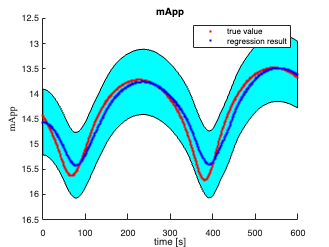

    if predictionStep == 1
        [t, x] = ode45(@(t, x)eomAttiOrb_h(t,x,const,earthVSOP,sat,jd), tstep_span, x_ode(i,:), options);
        x_ode(i+1,:) = x(end,:);
        x_reg(i+1,1:4) = x_ode(i+1,7:10); % [q]
        % x_reg(i+1,5:13) = x_reg(i,5:13); % [satPos, obsPos, sunPos]
        if strcmp(inputGP, "attitude, position, mApp_pastMean")

        % tstep_span後の位置情報が欲しい -----------
            x_reg(i+1,5:7) = x_ode(i+1,1:3) ./ r_valid_max; % [r]
    
            jdHistory_tmp = jd + s2day(t);
            jd = jd + s2day(t(end)); % jd を更新 for next step
            [yy, mm, dd, hh, m, s] = jd2gc(jdHistory_tmp);
            utc_tmp = datetime([yy, mm, dd, hh, m, s]);
            for ii = 1:1:length(t)
                dcmITRF2gcrf_tmp = itrf2gcrf(utc_tmp(ii), leapJD, iau06, eopDataAll); % International Terrestrial Reference Frame to Geocentric Celestial Reference Frame(inertial frame)
                qITRF2gcrf_tmp(ii,:) = dcm2q(4, dcmITRF2gcrf_tmp);
            end
            obsECI_tmp = qRotation(4, repmat(obsPosECEF, length(jdHistory_tmp),1), qITRF2gcrf_tmp);
            x_reg(i+1,8:10) =  obsECI_tmp(end,:) ./ obsECI_valid_max; % [obsECI]
    
            sunPosI_tmp = sun(jdHistory_tmp, const, earthVSOP);
            sunPosI_tmp = sunPosI_tmp .* 10^3; % [m]
            % x_reg(i+1,11:13) = sunPosI_tmp(end,:); % [sunPosI] % 一旦無視
        elseif strcmp(inputGP, "attitude, relativePosition, mApp_pastMean")
            jdHistory_tmp = jd + s2day(t);
            jd = jd + s2day(t(end)); % jd を更新 for next step
            [yy, mm, dd, hh, m, s] = jd2gc(jdHistory_tmp);
            utc_tmp = datetime([yy, mm, dd, hh, m, s]);
            for ii = 1:1:length(t)
                dcmITRF2gcrf_tmp = itrf2gcrf(utc_tmp(ii), leapJD, iau06, eopDataAll); % International Terrestrial Reference Frame to Geocentric Celestial Reference Frame(inertial frame)
                qITRF2gcrf_tmp(ii,:) = dcm2q(4, dcmITRF2gcrf_tmp);
            end
            obsECI_tmp = qRotation(4, repmat(obsPosECEF, length(jdHistory_tmp),1), qITRF2gcrf_tmp);
            
            x_reg(i+1, 5:7) = (x_ode(i+1, 1:3) - obsECI_tmp(end,:)) ./ obsToTarget_valid_max; % [r - obsECI]

            sunPosI_tmp = sun(jdHistory_tmp, const, earthVSOP);
            sunPosI_tmp = sunPosI_tmp .* 10^3; % [m]
        elseif strcmp(inputGP, "attitude, mApp_pastMean")
        elseif strcmp(inputGP, "attitude")
        end
    
        x_reg(i+1, inputDim) = (x_reg(i, inputDim) * tSpanPast + valid.mApp(i+1,1)) / (tSpanPast+1); % [mApp_pastMean], 観測値を使う．

- predictionStep == 2. input: x_reg(i, :), output: y_reg_mu(i, 2:end)

    elseif predictionStep == 2
        for j = 2:1:size(y_reg_mu, 2)
            [y_reg_mu(i+1,j), y_reg_var(i+1,j)] = gprNormal(x_reg(i,:), x_train(:,1:inputDim), y_train(:,j), params, Kinv_Dp); % input: 
        end
        y_reg_mu(i,2:end) = y_reg_mu(i,2:end) + y_train_mean(i,2:end);
        y_reg(i+1,2:5) = qMult_h(y_reg(i,2:5), rv2q(y_reg_mu(i,2:4)));
        y_reg(i+1,6:end) = y_reg(i,6:end) + y_reg_mu(i,5:end);
    end
end

- 最後にもう一回 observation step

[y_reg_mu(end, 1), y_reg_var(end, 1)] = gprNormal(x_reg(end, :), x_train(:,1:inputDim), y_train, params, Kinv_Do); % input: [q_k, satPos_k, obsPos_k, sunPos_k], output: [mApp_k]
y_reg(end, 1) = y_reg_mu(end, 1) + y_train_mean(1, 1); 
% y_reg(end,1) = y_reg_mu(end,1);

### export to csv

とりあえずしない

### plot

mkdir ../results/GP_static/
savedir = strcat(curdir, '/../results/GP_static/');

fignames = ["mApp"];
x_label = "time [s]";
y_labels = ["mApp"];

figure('Name', fignames(1));
plot_gpr(t_, y_reg(:,1), valid.mApp, y_reg_var(:,1), fignames(1), x_label, y_labels(1), savedir, 1);